## Strong and Weak Scaling with a Small Problem Size

For both scaling experiments the problem size began at N=100. For weak scaling, this number doubled each time the processors doubled for a final N value of 6400. This way, each processor would always have exactly 100 iterations to perform. The plots of speedup, efficiency are followed with analysis below.

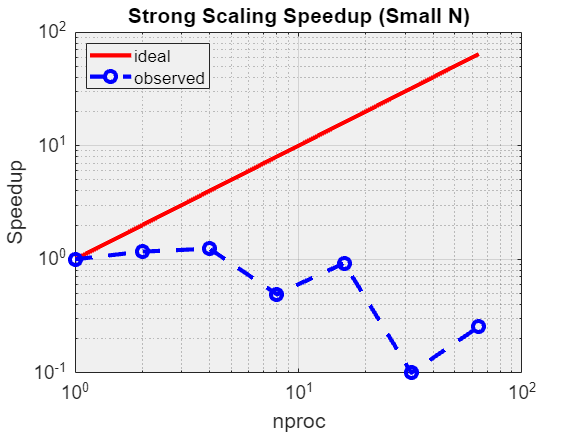

%Reading data
speedData=readmatrix('strongSmall.csv');
nproc=speedData(:,1);
time=speedData(:,2);
speedup = time(1)./time;
idealSpeedup = nproc;

%Speedup
loglog(nproc,idealSpeedup,'r-',nproc,speedup,'bo--','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Speedup','FontSize',14);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Strong Scaling Speedup (Small N)');
legend('ideal','observed','Location','northwest');

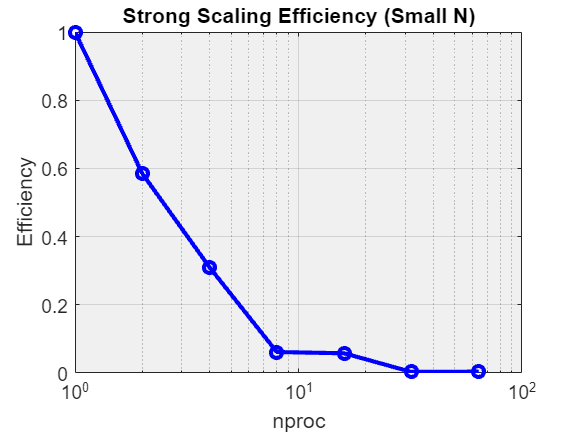


%Efficiency (Strong)
E = speedup./nproc;
semilogx(nproc,E,'bo-','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Efficiency','FontSize',14);
ylim([0 1]);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Strong Scaling Efficiency (Small N)');

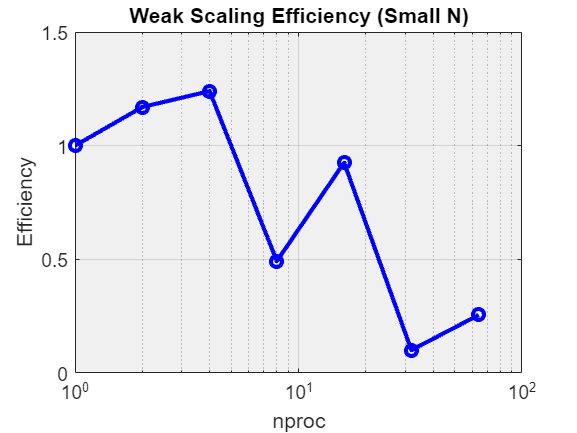


%Reading data
speedData=readmatrix('weakSmall.csv');
nproc=speedData(:,1);
time=speedData(:,2);
%Plotting
E=time(1)./time;
semilogx(nproc,speedup,'bo-','LineWidth',3,'MarkerSize',8);
grid on;
xlabel('nproc','FontSize',14);
ylabel('Efficiency','FontSize',14);
ylim([0 1.5]);
set(gca,'FontSize',14);
set(gca,'color',1/255*[240 240 240])
title('Weak Scaling Efficiency (Small N)');

Immediately I was drawn to the Weak Scaling Efficiency (Small N) plot. It is naturally impossible to be 100% efficient let alone ~125% efficient. This implies that, based on the formal definition, the machine is accomplishing more output than the work it is putting in. Because the problem size is so minute with respect to the computational power of the processors, it is possible that the hardware on the specific processor on the specific node was running faster than the times before (or maybe I just defied the second law of thermodynamics). The time difference between runs is so small that the slightest improvement in hardware between runs could have caused this jump.

When it comes to the strong scaling plots, it is quite obvious that small problem sizes are not good for multiple processors. As the number of processors increases, the efficiency steadily decreases along with the speedup. This is because the problem size is so small, one processor can do the calculations just as fast as a million could (probably much faster) because it does not have to spend time on communication. Parallel computing is about finding a perfect balance of processors for the given problem size in order to maximize time spent computing and minimize time spent communicating. In the case of N = 1000, no more than 1 processor is every really needed.